## **In the Name of God**

# Wireless Communication

# `CA#2 Part#1`

# **Alireza Javid**

# **810198375**

rng(1)
numBits = 1e6;         
SNRdB = -20:1:20;   

### Part 1: BPSK without CSI

ber1 = zeros(size(SNRdB));
ber2 = zeros(size(SNRdB));
for i = 1:length(SNRdB)
    % Generate random bits
    bits = bit_gen(numBits,1);
    % BPSK modulation
    x = 2*bits - 1;  % Map 0 to -1 and 1 to 1
    % Complex channel transmission
    h1 = (randn(numBits, 1) + 1i*randn(numBits, 1))/sqrt(2);  % Complex Gaussian noise
    h2 = ones(numBits, 1);
    snr = 10^(SNRdB(i)/10); 
    w =  sqrt(0.5/snr) * (randn(numBits, 1) + 1i*randn(numBits, 1));
    y1 = x.*h1 + w; 
    y2 = x.*h2 + w;
    % BPSK demodulation
    receivedBits1 = real(y1) > 0;  % Thresholding at 0 to detect bits
    receivedBits2 = real(y2) > 0;
    numErrors1 = sum(bits ~= receivedBits1);
    numErrors2 = sum(bits ~= receivedBits2);
    ber1(i) = numErrors1 / numBits;
    ber2(i) = numErrors2 / numBits;
end

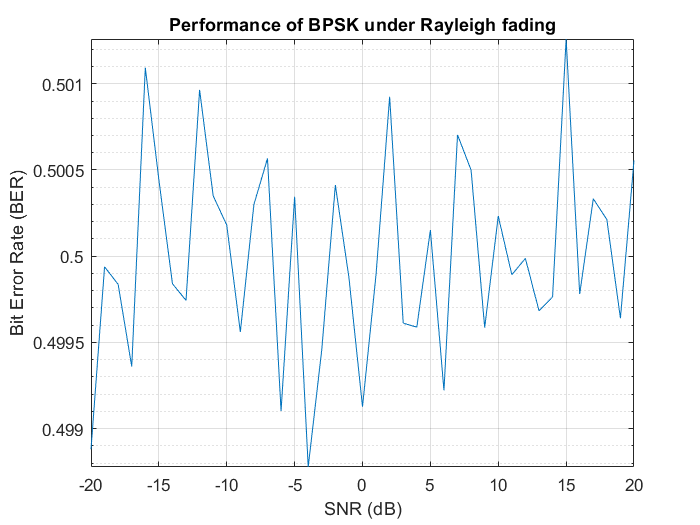

figure;
semilogy(SNRdB,ber1)
grid on
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
title('Performance of BPSK under Rayleigh fading');

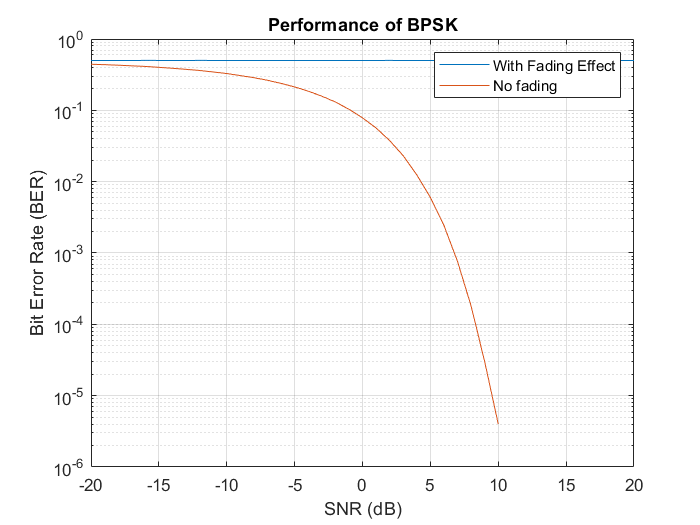

figure;
semilogy(SNRdB,ber1,SNRdB,ber2)
grid on
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
title('Performance of BPSK');
legend({'With Fading Effect','No fading'})

### Part 2: Binary Method

ber1_binary = zeros(size(SNRdB));
ber2_binary = zeros(size(SNRdB));
for i = 1:length(SNRdB)
    % Generate random bits
    bits_t1 = bit_gen(numBits,1);
    bits_t2 = -(bits_t1 - 1);
    % Complex channel transmission
    h1 = (randn(numBits, 1) + 1i*randn(numBits, 1))/sqrt(2);  
    h2 = ones(numBits, 1);
    snr = 10^(SNRdB(i)/10);  
    w1 =  sqrt(0.5/snr) * (randn(numBits, 1) + 1i*randn(numBits, 1));
    w2 =  sqrt(0.5/snr) * (randn(numBits, 1) + 1i*randn(numBits, 1));
    x_t1 = bits_t1;
    x_t2 = bits_t2;
    y1_t1 = x_t1.*h1 + w1;
    y1_t2 = x_t2.*h1 + w2;
    y2_t1 = x_t1.*h2 + w1;
    y2_t2 = x_t2.*h2 + w2;
    receivedBits1 = abs(y1_t1) > abs(y1_t2);
    receivedBits2 = abs(y2_t1) > abs(y2_t2);
    numErrors1 = sum(receivedBits1 ~= bits_t1);
    numErrors2 = sum(receivedBits2 ~= bits_t1);
    ber1_binary(i) = numErrors1 / numBits;
    ber2_binary(i) = numErrors2 / numBits;
end

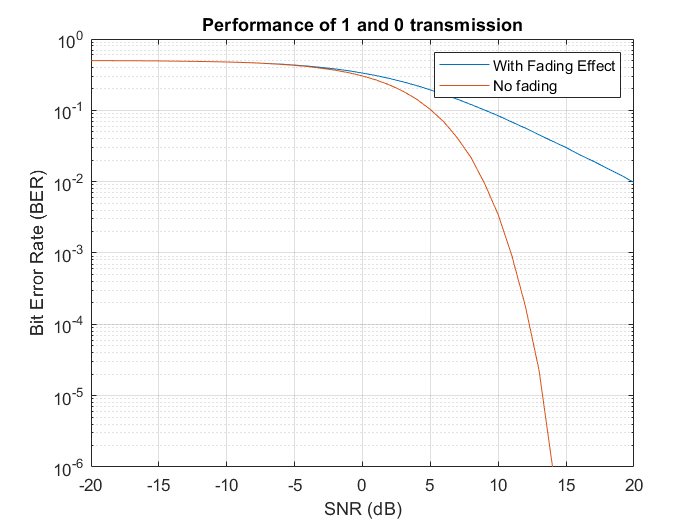

figure;
semilogy(SNRdB,ber1_binary,SNRdB,ber2_binary)
grid on
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
title('Performance of 1 and 0 transmission');
legend({'With Fading Effect','No fading'})

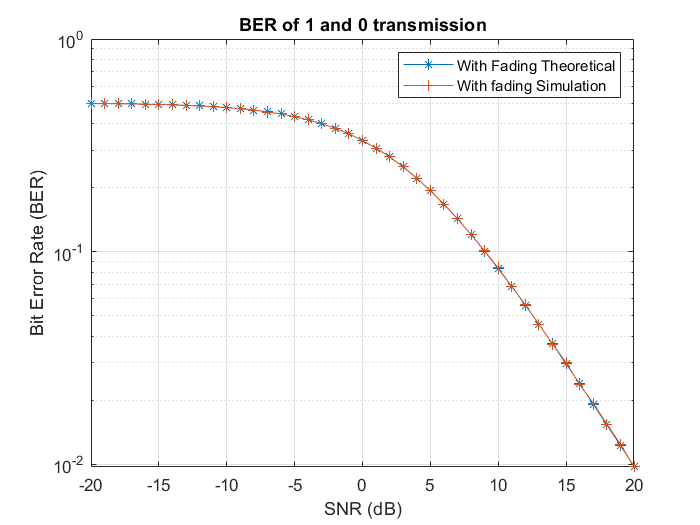

theoricError=1./(2+db2pow(SNRdB));
figure;
semilogy(SNRdB,theoricError,'-*',SNRdB,ber1_binary,'-+')
grid on
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
title('BER of 1 and 0 transmission');
legend({'With Fading Theoretical','With fading Simulation'})

### Part 3: BPSK with CSI

ber_BPSK_CSI = zeros(size(SNRdB));
for i = 1:length(SNRdB)
    % Generate random bits
    bits = bit_gen(numBits,1);
    % BPSK modulation
    x = 2*bits - 1;  % Map 0 to -1 and 1 to 1
    h = (randn(numBits, 1) + 1i*randn(numBits, 1))/sqrt(2);  
    snr = 10^(SNRdB(i)/10);  
    w =  sqrt(0.5/snr) * (randn(numBits, 1) + 1i*randn(numBits, 1));
    y = x.*h + w;
    a = conj(h) ./ abs(h);
    z = a.*y;
    % BPSK demodulation
    receivedBits = real(z) > 0;  % Thresholding at time slots to detect bits
    numErrors = sum(receivedBits ~= bits);
    ber_BPSK_CSI(i) = numErrors / numBits;
end

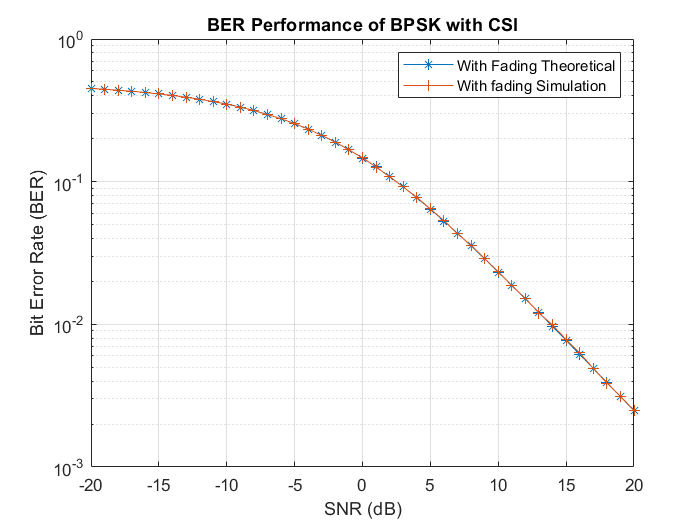

theory_error=(1-sqrt((db2pow(SNRdB))./(1+db2pow(SNRdB))))/2;
figure;
semilogy(SNRdB,theory_error,'-*',SNRdB,ber_BPSK_CSI,'-+')
grid on
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
title('BER Performance of BPSK with CSI');
legend({'With Fading Theoretical','With fading Simulation'})

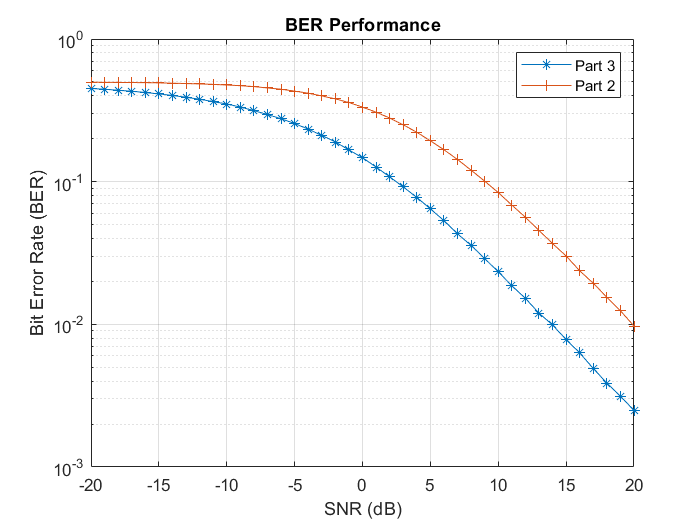

figure;
semilogy(SNRdB,ber_BPSK_CSI,'-*',SNRdB,ber1_binary,'-+')
grid on
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
title('BER Performance');
legend({'Part 3','Part 2'})

### Part 4: QPSK with CSI

ber_qpsk = zeros(size(SNRdB));
h = (randn(numBits, 1) + 1i*randn(numBits, 1))/sqrt(2);
for i = 1:length(SNRdB)
    % Generate random bits
    bits = bit_gen(numBits,1);
    % QPSK modulation
    x = qpsk_modulation(bits);
    snr = 10^(SNRdB(i)/10); 
    w =  sqrt(0.5/snr) * (randn(numBits, 1) + 1i*randn(numBits, 1));
    y = x.*h + w; 
    a = conj(h) ./ abs(h);
    z = a.*y;
    % QPSK demodulation
    x_det = qpsk_demodulation(z); 
    numErrors = sum(round(x,4) ~= round(x_det,4));
    ber_qpsk(i) = numErrors / numBits;
end

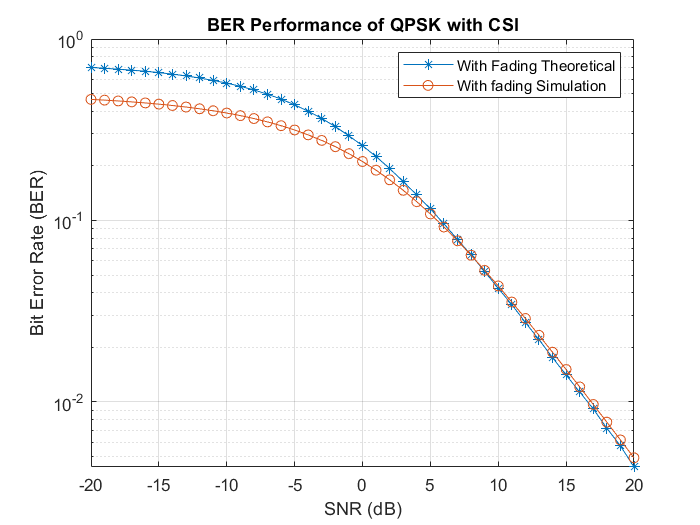

figure;
theory_error=0.5*(1-sqrt((db2pow(SNRdB))./(2+db2pow(SNRdB))));
semilogy(SNRdB,ber_qpsk,'-*',SNRdB,theory_error,'-o')
grid on
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
title('BER Performance of QPSK with CSI');
legend({'With Fading Theoretical','With fading Simulation'})

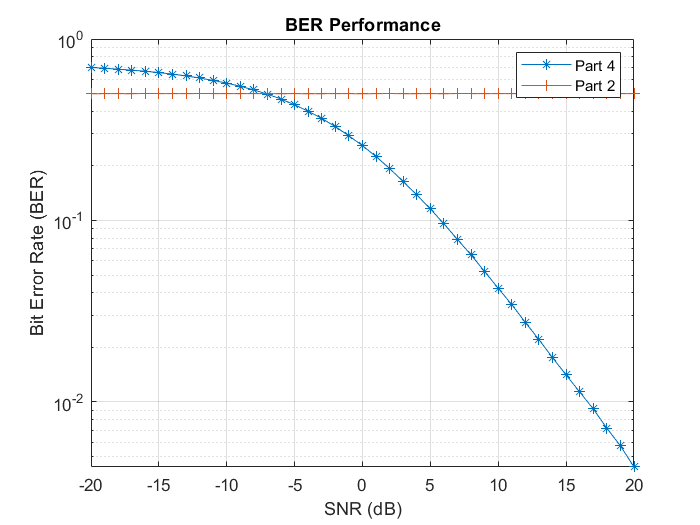

figure;
semilogy(SNRdB,ber_qpsk,'-*',SNRdB,ber1,'-+')
grid on
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
title('BER Performance');
legend({'Part 4','Part 2'})

### Part 5: Time Diversity

SNRdB=-10:1:10;
ber_time1 = time_diversity(1,SNRdB, numBits);
ber_time2 = time_diversity(2,SNRdB, numBits);
ber_time3 = time_diversity(3,SNRdB, numBits);
ber_time4 = time_diversity(4,SNRdB, numBits);
ber_time5 = time_diversity(5,SNRdB, numBits);

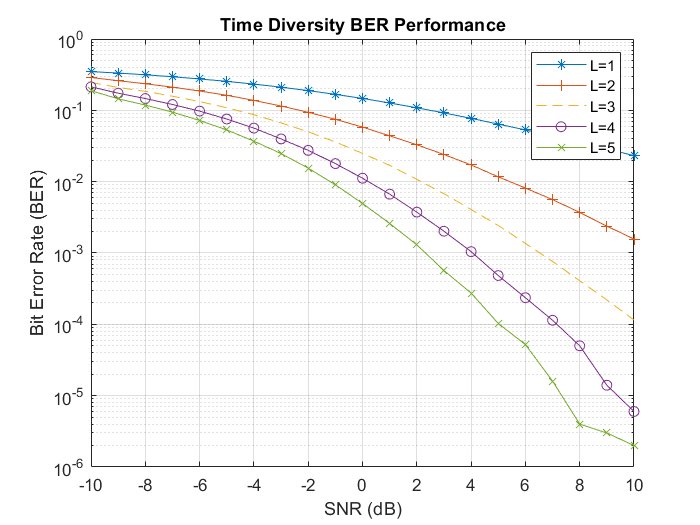

semilogy(SNRdB,ber_time1,'-*',SNRdB,ber_time2,'-+', SNRdB,ber_time3, '--', ...
    SNRdB,ber_time4,'-o', SNRdB,ber_time5, '-x')
grid on
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
title('Time Diversity BER Performance');
legend({'L=1','L=2','L=3','L=4','L=5'})

ber_th_time1 = theory_time_diversity(1,SNRdB);
ber_th_time2 = theory_time_diversity(2,SNRdB);
ber_th_time3 = theory_time_diversity(3,SNRdB);
ber_th_time4 = theory_time_diversity(4,SNRdB);
ber_th_time5 = theory_time_diversity(5,SNRdB);

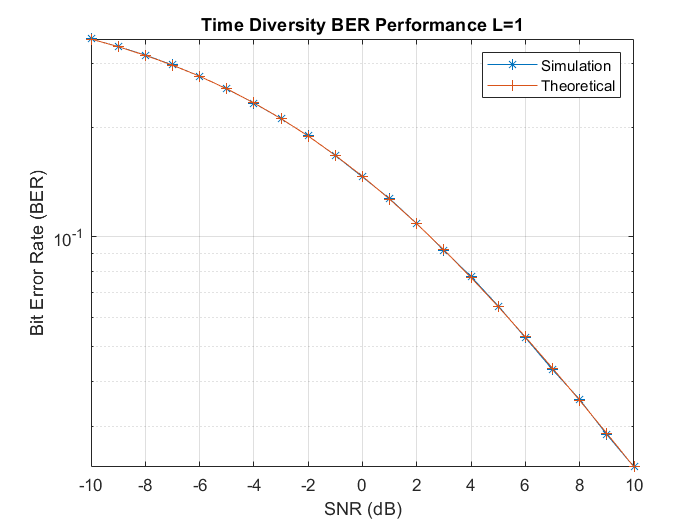

semilogy(SNRdB,ber_time1,'-*',SNRdB,ber_th_time1,'-+')
grid on
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
title('Time Diversity BER Performance L=1');
legend({'Simulation','Theoretical'})

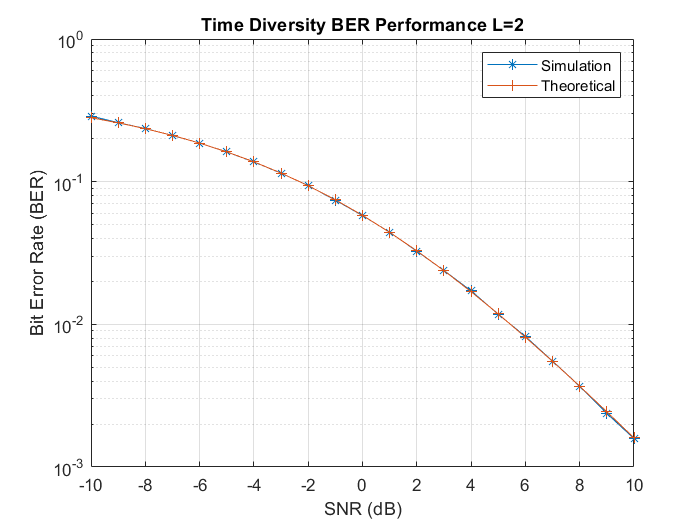

semilogy(SNRdB,ber_time2,'-*',SNRdB,ber_th_time2,'-+')
grid on
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
title('Time Diversity BER Performance L=2');
legend({'Simulation','Theoretical'})

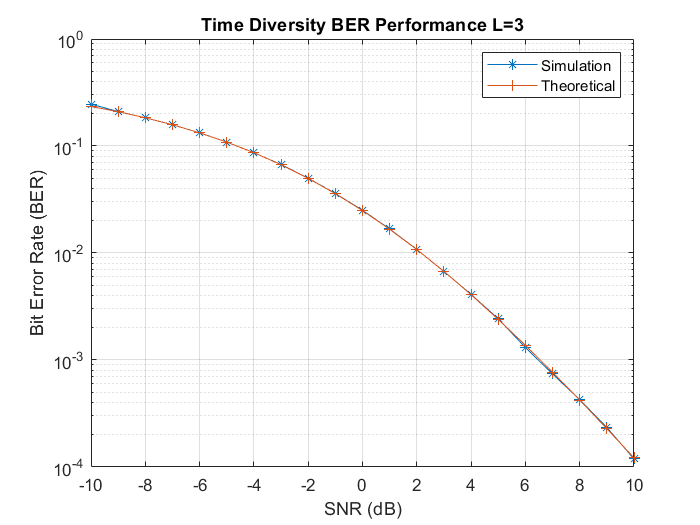

semilogy(SNRdB,ber_time3,'-*',SNRdB,ber_th_time3,'-+')
grid on
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
title('Time Diversity BER Performance L=3');
legend({'Simulation','Theoretical'})

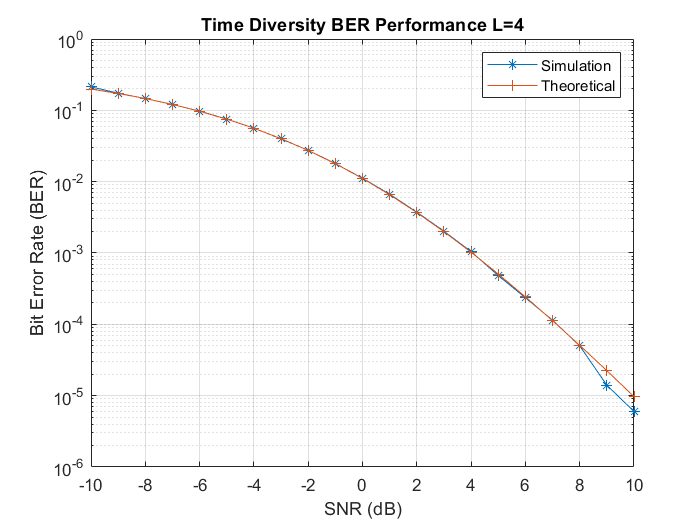

semilogy(SNRdB,ber_time4,'-*',SNRdB,ber_th_time4,'-+')
grid on
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
title('Time Diversity BER Performance L=4');
legend({'Simulation','Theoretical'})

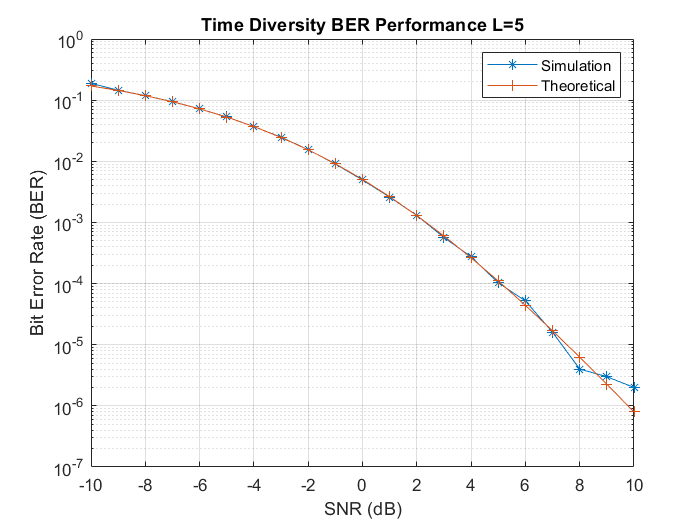

semilogy(SNRdB,ber_time5,'-*',SNRdB,ber_th_time5,'-+')
grid on
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
title('Time Diversity BER Performance L=5');
legend({'Simulation','Theoretical'})

### Part 6: Alamuti 2Tx-1Rx

SNRdB = -10:1:15;  
ber_alam = zeros(size(SNRdB));
L = 2;
bits1 = bit_gen(numBits,1);
bits2 = bit_gen(numBits,1);
x1 = 2*bits1 - 1;
x2 = 2*bits2 - 1;
total_gain = zeros(numBits, 1);
h1 = (randn(numBits, 1) + 1i*randn(numBits, 1))/sqrt(2);
h2 = (randn(numBits, 1) + 1i*randn(numBits, 1))/sqrt(2);
for i = 1:length(SNRdB)
    snr = 0.5*10^(SNRdB(i)/10);  % Convert SNR from dB to linear scale
    received_signal = zeros(numBits, 1);
    w1 =  sqrt(0.5/snr) * (randn(numBits, 1) + 1i*randn(numBits, 1));
    w2 =  sqrt(0.5/snr) * (randn(numBits, 1) + 1i*randn(numBits, 1));
%     total_gain = total_gain + abs(h).^2;
%     a = conj(h) ./ (sqrt(total_gain));
    y_ts1 = x1.*h1 + x2.*h2 + w1;
    y_ts2 = -conj(x2).*h1 + conj(x1).*h2 + w2;
    %define metrics
    z1 = conj(h1) .* y_ts1 + h2 .* conj(y_ts2);
    z2 = conj(h2) .* y_ts1 - h1 .* conj(y_ts2);
    % BPSK demodulation
    bit_det1 = real(z1) > 0;  % Thresholding to detect bits
    bit_det2 = real(z2) > 0;  % Thresholding to detect bits
    % Calculate Bit Error Rate (BER)
    numErrors1 = sum(bits1 ~= bit_det1);
    numErrors2 = sum(bits2 ~= bit_det2);
    ber_alam(i) = (numErrors1 + numErrors2) / (2*numBits);
end

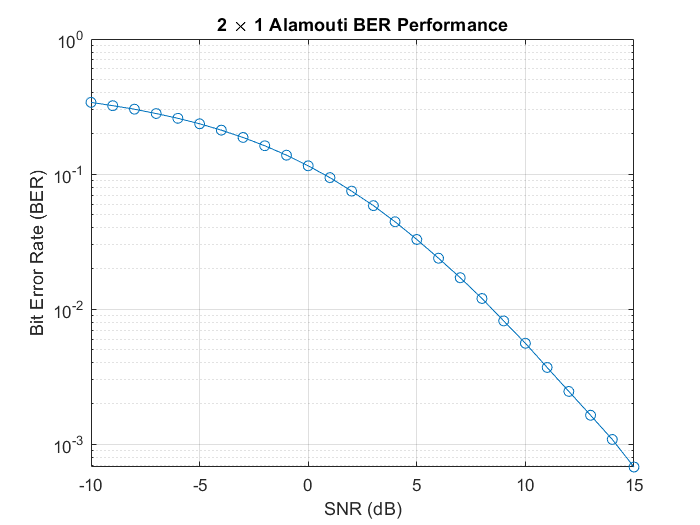

figure;
semilogy(SNRdB,ber_alam,'-o');
grid on
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
title('2 \times 1 Alamouti BER Performance');

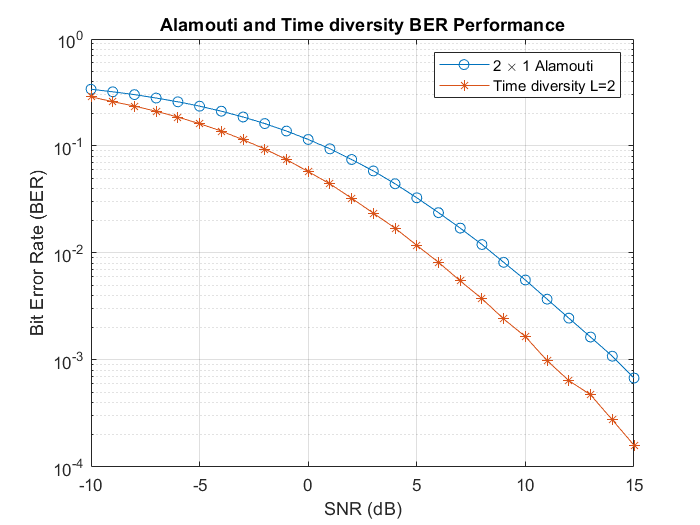

figure;
ber_time2 = time_diversity(2,SNRdB, numBits);
semilogy(SNRdB,ber_alam,'-o', SNRdB,ber_time2,'-*');
grid on
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
title('Alamouti and Time diversity BER Performance');
legend({'2 \times 1 Alamouti','Time diversity L=2'})

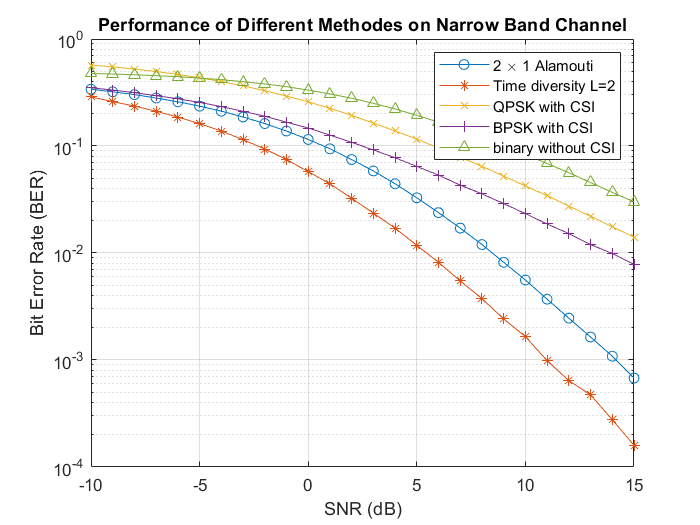

figure;
semilogy(SNRdB,ber_alam,'-o', SNRdB,ber_time2,'-*', SNRdB,ber_qpsk(11:36),'-x', ...
    SNRdB,ber_BPSK_CSI(11:36),'-+', SNRdB,ber1_binary(11:36),'-^');
grid on
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
title('Performance of Different Methodes on Narrow Band Channel');
legend({'2 \times 1 Alamouti','Time diversity L=2', 'QPSK with CSI', ...
    'BPSK with CSI', 'binary without CSI'})

function b = bit_gen(N, k)
    b = randi([0 1], N, k);
    b = double(b);
end

function x = qpsk_modulation(bits)
    x = zeros(length(bits), 1);
    x(1:length(bits)*0.25)=1+1j;
    x(length(bits)*0.25:length(bits)*0.5)=1-1j;
    x(length(bits)*0.5:length(bits)*0.75)=-1+1j;
    x(length(bits)*0.75:length(bits)*1)=-1-1j;
end

function x_det = qpsk_demodulation(y)
    angles = angle(y) * 180 / pi;
    angles(angles >= 0 & angles < 90) = 45;
    angles(angles >= 90 & angles < 180) = 135;
    angles(angles >= -90 & angles < 0) = -45;
    angles(angles >= -180 & angles < -90) = -135;
    x_det = sqrt(2)*exp(1i * angles * pi / 180);
end

function ber_timediv = time_diversity(L, SNRdB, numBits)
    ber_timediv = zeros(size(SNRdB));
    bits = bit_gen(numBits,1);
    x = 2*bits - 1;
    total_gain = zeros(numBits, 1);
    for i = 1:length(SNRdB)
        snr = 10^(SNRdB(i)/10);
        received_signal = zeros(numBits, 1);
        for j=1:L
            h = (randn(numBits, 1) + 1i*randn(numBits, 1))/sqrt(2);
            w =  sqrt(0.5/snr) * (randn(numBits, 1) + 1i*randn(numBits, 1));
            y = x.*h + w; 
            total_gain = total_gain + abs(h).^2;
            a = conj(h) ./ (sqrt(total_gain));
            z = a.*y;
            received_signal = received_signal + z;
        end
            % BPSK demodulation
            bit_det = real(received_signal) > 0;  % Thresholding to detect bits
            numErrors = sum(bits ~= bit_det);
            ber_timediv(i) = numErrors / numBits;
    end
end

function ber=theory_time_diversity(L, SNRdB)
    ber = zeros(size(SNRdB));
    for i = 1 : length(SNRdB)
        snr=db2pow(SNRdB(i));
        u = sqrt(snr/(1+snr));
        alpha = 0;
        for k = 0 : L - 1
            alpha = alpha + nchoosek(L -1 +k , k) * ((1+u)/2)^k;
        end
        ber(i) = ((1-u)/2)^L *alpha;
    end 
end
